% function mm_track_main()
clc; clear; close all;

%% -------- Project paths (edit if needed) --------
project_root = './';
addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'data'));

%% -------- Dimensions --------
% η = [v; w; q_a]  -> size m = 5 (2 base + 3 arm) in your setup
% q ∈ R^8  (x_m, y_m, θ_m, θ_r, θ_l, θ1, θ2, θ3)
m  = 5;              % length(eta)
nq = 8;              % length(q)

%% -------- Controller gains (2nd-order shaping) --------
% Choose natural freq & damping; Kp = ω_n^2, Kd = 2 ζ ω_n
wn  = [0.8 0.8 1.2 1.2 1.0];   % rad/s, per-channel
zeta= [1.0 1.0 1.0 1.0 1.0];   % critically damped default
Kp  = diag(wn.^2);
Kd  = diag(2*zeta.*wn);

%% -------- Desired trajectory (edit in desired_eta.m) --------
% Example: smooth sinusoids for all channels, designed to be feasible.
traj = @desired_eta;  % returns eta_d, etad_d, etadd_d at time t

%% -------- Initial conditions --------
q0      = [0; 0; 0; 0; 0; 0; 0; 0];     % base at origin, arm zeros
eta0    = zeros(m,1);                   % start at rest
etadot0 = zeros(m,1);
x0      = [q0; eta0; etadot0];          % state = [q; eta; etadot]

%% -------- Simulation options --------
Tend = 30;
opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.01);

%% -------- Pack user data for ODE --------
ud.Kp = Kp; ud.Kd = Kd; ud.traj = traj;
ud.model = make_model_handles();  % MODEL HOOKS (map to your functions)

%% -------- Simulate closed loop --------
fprintf('▶️  Simulating closed-loop tracking (computed torque)…\n');

▶️  Simulating closed-loop tracking (computed torque)…


tic;
[t, x] = ode45(@(t,x) mm_closedloop_ode(t, x, ud), [0 Tend], x0, opts);
toc;

Elapsed time is 0.403290 seconds.


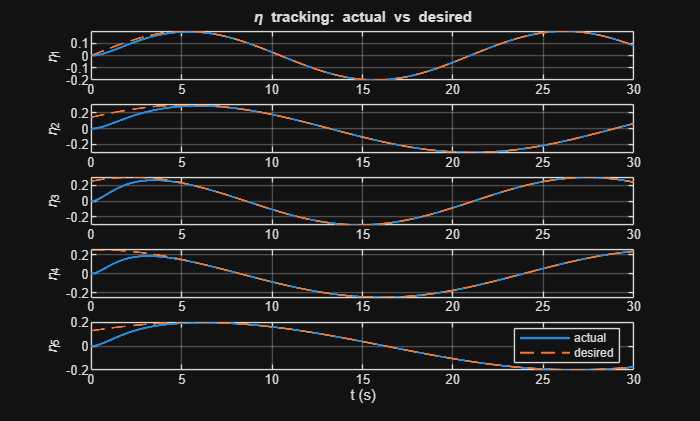


%% -------- Unpack results --------
q       = x(:, 1:nq);
eta     = x(:, nq+(1:m));
etadot  = x(:, nq+m+(1:m));

% Desired signals (for plotting)
eta_d   = zeros(numel(t), m);
etad_d  = zeros(numel(t), m);
for k = 1:numel(t)
    [ed, edd, ~] = ud.traj(t(k)); %#ok<ASGLU>
    eta_d(k,:)  = ed.';
    etad_d(k,:) = edd.';
end

%% -------- Plots --------
figure('Name','η tracking'); 
for i=1:m
    subplot(m,1,i);
    plot(t, eta(:,i), 'LineWidth', 1.4); hold on; grid on;
    plot(t, eta_d(:,i), '--', 'LineWidth', 1.2);
    ylabel(sprintf('\\eta_%d',i),'Interpreter','tex');
    if i==1, title('\eta tracking: actual vs desired'); end
end
xlabel('t (s)'); legend('actual','desired');

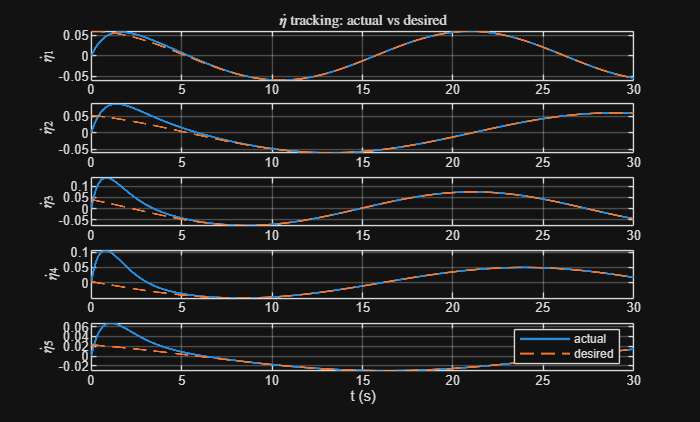


figure('Name','\dot{\eta} tracking');
for i=1:m
    subplot(m,1,i);
    plot(t, etadot(:,i), 'LineWidth', 1.4); hold on; grid on;
    plot(t, etad_d(:,i), '--', 'LineWidth', 1.2);
    ylabel(sprintf('$\\dot{\\eta}_%d$',i),'Interpreter','latex');
    if i==1, title('$\dot{\eta}$ tracking: actual vs desired','Interpreter','latex'); end
end
xlabel('t (s)'); legend('actual','desired');

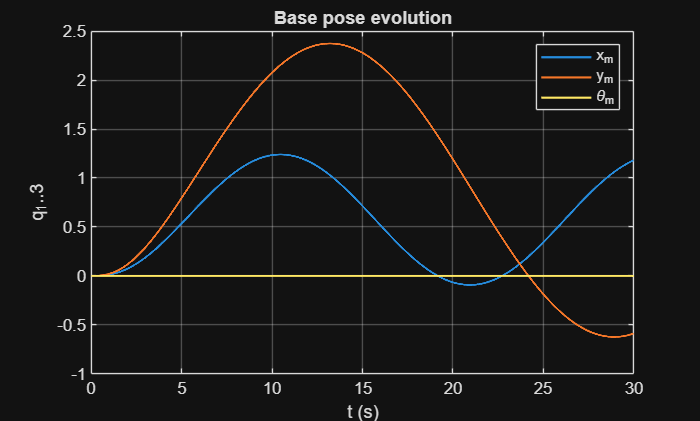


figure('Name','Base pose q(1:3)');
plot(t, q(:,1:3), 'LineWidth', 1.3); grid on;
xlabel('t (s)'); ylabel('q_1..3'); legend('x_m','y_m','\theta_m');
title('Base pose evolution');


fprintf('✅ Done.\n');

✅ Done.


% end
function dx = mm_closedloop_ode(t, x, ud)
% State: x = [q; eta; etadot]
% q̇ = R(q) * eta
% η̈ = M1^{-1} (B1 τ - C1 η - G1)
% τ = pinv(B1) [M1 v + C1 η + G1],  v = η̈_d + Kd(η̇_d − η̇) + Kp(η_d − η)

% -------- unpack --------
Kp   = ud.Kp; 
Kd   = ud.Kd; 
traj = ud.traj;
mdl  = ud.model;

nq = mdl.nq; m = mdl.m;
q      = x(1:nq);
eta    = x(nq+(1:m));
etadot = x(nq+m+(1:m));

% -------- desired signals --------
[eta_d, etad_d, etadd_d] = traj(t);

% -------- model terms --------
M1 = mdl.M1(q);
C1 = mdl.C1(q, eta);
G1 = mdl.G1(q);
B1 = mdl.B1(q);
R  = mdl.R(q);

% -------- computed-torque control --------
e   = (eta_d  - eta);
ed  = (etad_d - etadot);
v   = etadd_d + Kd*ed + Kp*e;

tau = pinv(B1) * (M1*v + C1*eta + G1);

% -------- plant dynamics --------
etaddot = M1 \ (B1*tau - C1*eta - G1);
qdot    = R * eta;

dx = [qdot; etadot; etaddot];
end
function [eta_d, etad_d, etadd_d] = desired_eta(t)
% Example: smooth, bounded references for 5 channels
%   [v, w, q1dot, q2dot, q3dot]  with low frequencies
A  = [0.2; 0.3; 0.3; 0.25; 0.2];     % amplitudes
w  = [0.3; 0.2; 0.25; 0.2; 0.15];    % rad/s
ph = [0; 0.5; 1.0; 1.5; 0.7];        % phase offsets

eta_d   = A .* sin(w*t + ph);
etad_d  = A .* (w) .* cos(w*t + ph);
etadd_d = -A .* (w.^2) .* sin(w*t + ph);
end
function mdl = make_model_handles()
% Map these to your pre-generated numeric functions.
% Replace STUBS with your own (e.g., mm_M1_fun(q), mm_C1_fun(q,eta), etc.)

mdl.nq = 8;       % q size
mdl.m  = 5;       % eta size

% ---- Replace these 5 with your true numeric functions ----
mdl.M1 = @(q) M1_stub(q);                 % [m x m]
mdl.C1 = @(q,eta) C1_stub(q,eta);         % [m x m] * eta (we use C1*eta form)
mdl.G1 = @(q) G1_stub(q);                 % [m x 1]
mdl.B1 = @(q) B1_stub(q);                 % [m x m] or [m x nu]
mdl.R  = @(q) R_stub(q);                  % [nq x m]
end

% ------------------- STUBS -------------------
function M = M1_stub(~)
m = 5; 
M = eye(m);     % <-- replace with: mm_M1_fun(q)
end
function C = C1_stub(~,~)
m = 5; 
C = zeros(m);   % <-- replace with: mm_C1_fun(q,eta)
end
function G = G1_stub(~)
m = 5; 
G = zeros(m,1); % <-- replace with: mm_G1_fun(q)
end
function B = B1_stub(~)
m = 5; 
B = eye(m);     % <-- replace with: mm_B1_fun(q)
end
function R = R_stub(~)
R = [ ...       % nq x m  (8x5)
    1 0 0 0 0;  % x_m dot depends on v only in this stub
    0 1 0 0 0;  % y_m dot (stub)
    0 0 0 0 0;  % theta_m dot (stub)
    0 0 0 0 0;  % theta_r dot
    0 0 0 0 0;  % theta_l dot
    0 0 1 0 0;  % theta1 dot = eta3
    0 0 0 1 0;  % theta2 dot = eta4
    0 0 0 0 1]; % theta3 dot = eta5
% <-- replace with: mm_R_fun(q)
end
